%% May need to mex the following cpp before running this file
% mex randCppFun.cpp

%% For one general betas and city-specific I0 of217 citeis
addpath('mossong_2008')
load tmpCaseRateUS.mat
load BasicSettings.mat;
shiftWeek = 0;
vaccin.vaccin_Num = 0;
vaccin.drug_Num = 0;
tmpR = tmpCaseRateUS( (shiftWeek+38):end);
rng('default')

Apply drug and vaccination to model

% Epi (EPI) scenarios
EPIs = [0.13, 0.18, 0.188]; % fit to Houston since Nov. 21 by running getR0dyn_Houston.m
scalingV = 1.62; % fit by Jul_Step_1_fit2009.mlx, the

% Vaccine (VX) scenarios
% VX1: “Early”: Vaccine available 100 days after September 1
% VX2: “Normal”: Vaccine available 150 days after September 1
% Delay from arrival to administration is 1 week (same as 2009)
VXs = [0, 1, 2, 3]; % 0 for no, 1 for VX1, 2 for VX2;    3 for real

% School closure (SC) scenarios
% SC1: Illness prevalence trigger, early (VX1) vaccine availability
% SC2: Close at Day X, early (VX1) vaccine availability
% SC3: Illness prevalence trigger, normal (VX2) vaccine availability
% SC4: Close at Day X, normal (VX2) vaccine availability
SCs = 0:1:4; % 0 for no SC

% Antiviral (AV) scenario
AVs = [0, 1]; % 0 for no drug; 1 for drug

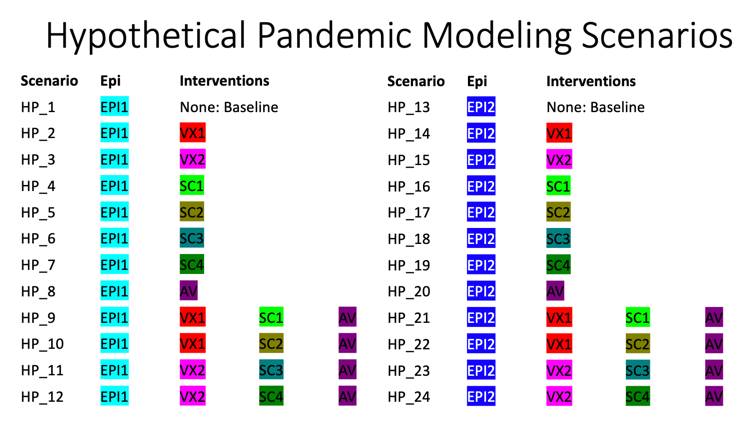

% EPI, VX, SC, AV, flag_realVX
Strategy_List = [1,0,0,0,0;1,1,0,0,0;1,2,0,0,0;1,0,1,0,0;1,0,2,0,0;1,0,3,0,0;1,0,4,0,0;1,0,0,1,0;1,1,1,1,0;1,1,2,1,0;1,2,3,1,0;1,2,4,1,0;2,0,0,0,0;2,1,0,0,0;2,2,0,0,0;2,0,1,0,0;2,0,2,0,0;2,0,3,0,0;2,0,4,0,0;2,0,0,1,0;2,1,1,1,0;2,1,2,1,0;2,2,3,1,0;2,2,4,1,0;3,0,0,0,1;3,3,0,0,1;3,0,0,1,1;3,3,0,1,1;3,0,3,0,1;3,0,4,0,1;3,3,3,1,1;3,3,4,1,1];

fitness{1} = DL; % incidence of Symptomatic illnesses

fitness{2} = DH_shf; % incidence of Hospitalizations

fitness{3} = DL; % incidence of Deaths

fitness{4} = YT; % incidence of Treated

numcores = feature('numcores')

numcores = 8

if numcores>8;   parpool(16); end
hourlyPerD = 5;
clear res4s res5s
for iii=1:10
    %     parfor i = 1:32
    for i = 1:32
        temp = [0.19, 2, 5.2];
        
        i2 = i;
        j=1;
        EPI = Strategy_List(i2,j); j=j+1;
        temp(1) = EPIs(EPI);
        VX = Strategy_List(i2,j); j=j+1;
        SC = Strategy_List(i2,j); j=j+1;
        AV = Strategy_List(i2,j); j=j+1;
        flag_realVX = Strategy_List(i2,j); j=j+1;  % whether using real vaccine supply in US
        
        % set transmission rate
        iX = temp(1); betasRatio = temp(2); iI0 = temp(3);
        
        % set rand seeds
        tempiii = mod(ceil((now*100000 - floor(now*100000))*100000)+iii, 1000);
        rng(tempiii);
        
        for jjj=1:tempiii
            randBin(100, 0.2, 1); randPois(100, 1);
        end
        
        % Place of Emergence: U.S.A. (100 cases in Wichita, KS), CBSA: 48660
        LocationNumTest = find(tempMG==48660);
        Tpeirod = 7*53;
        sto1div5 = 1; % from 5 days to 3 and 7 days by triangular distribution
        fitness = model_SECIR_V20_sto_Jul([iX iI0], xi, Pop_Metro, ...
            vaccin, Humidity_mean_data, ageG2, ageG, ...
            Pop_MetroAll, Humidity_mean_day_data, [], LocationNumTest, [], [], ...
            shiftWeek, Pop_Metro17, betasRatio, [], VX, SC, AV, flag_realVX, EPI, Tpeirod, sto1div5);
        
        res4 = plotByDL4_ageG(fitness, hourlyPerD, Pop_MetroAll, tmpR, shiftWeek, Pop_Metro, tmpAgeAttack38_52_propor);
        for ires4 = 1:length(res4)
            res4{ires4} = res4{ires4}/scalingV;
        end
        res4s{i} = res4;
        res5 = plotByDL4(fitness, hourlyPerD, Pop_MetroAll, tmpR, shiftWeek, Pop_Metro, tmpAgeAttack38_52_propor);
        for ires4 = 1:length(res5)
            res5{ires4} = res5{ires4}/scalingV;
        end
        res5s{i} = res5;
    end
    
    save( strcat('augMats/Aug11_sims_humidity', num2str( round(now*1000000) ), '.mat') )% save( strcat('augMats/Aug11_sims_357_', num2str( round(now*1000000) ), '.mat') )
end
